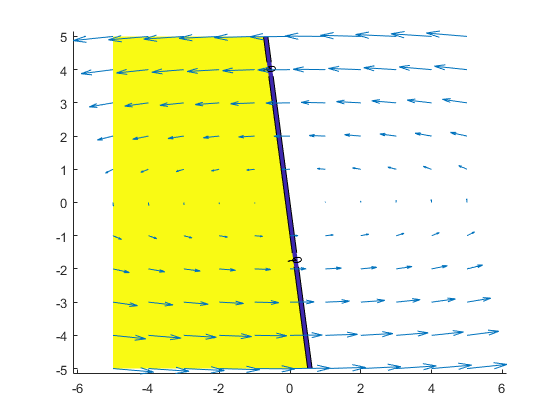

clear all
close all
A1 = [-1 -100;
    10 -1];
A2 = [1 10;
    -100 1];
E12 = [-8 -1];
E21 = [2 -1];
Q = [E12; E21].'*[0 1; 1 0] * [E12; E21];
R12 = eye(2); R21 = eye(2);

dx1 = @(x) A1.*x; %function desribing q1
dx2 = @(x) A2.*x; %function desribing q2

%plotting settings
min = -5;
max = 5;
stepsize = 1;
figure()
%plotting everything individually to validate functionality
[X,Y,u,v] = vectorfield(A1,min,max,stepsize);
hold on

[X,Y,p] = valuefield(E12,min,max,stepsize);
contourf(X,Y,p,[0 1],'ShowText','on')

quiver(X,Y,u,v)
hold off

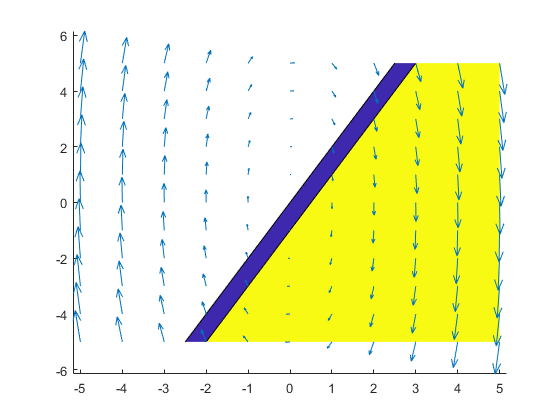


figure()
hold on
[X,Y,p] = valuefield(E21,min,max,stepsize);
contourf(X,Y,p,[0 1])

[X,Y,u,v] = vectorfield(A2,min,max,stepsize);
quiver(X,Y,u,v)



hold off

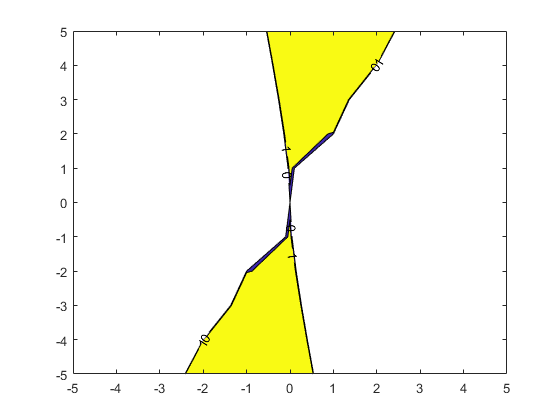


[X,Y,Qp] = Qfield(Q,min,max,stepsize);
contourf(X,Y,Qp,[0 1],'ShowText','on')

vectorsize = 0.5

vectorsize = 0.5000

mapsize = 0.01

mapsize = 0.0100


min = -5

min = -5

max = 5

max = 5

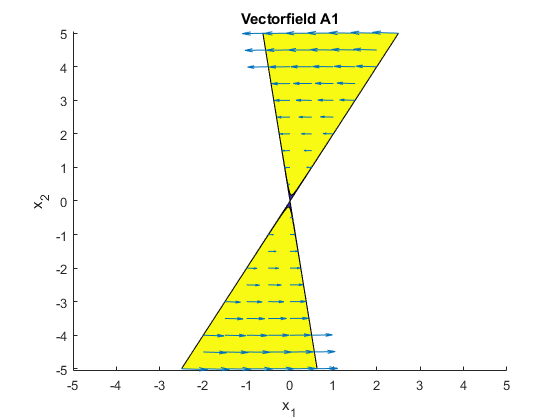


figure()
clf; hold on
%plotting the invariant map
[X,Y,Qp] = Qfield(Q,min,max,mapsize);
contourf(X,Y,Qp,[0 0.1])

%computing and plotting the vectorfield
[X,Y,u,v] = vectorfield(A1,min,max,vectorsize); %computing vectorsfield
[X,Y,Qp] = Qfield(Q,min,max,vectorsize); %recomputing feasible area to create binary map
map = zeros(length(u)); map(Qp>=0) = 1;
quiver(X,Y,u.*map,v.*map) %plotting the mapped vectorfield
title('Vectorfield A1')
xlabel('x_1'); ylabel('x_2')

hold off

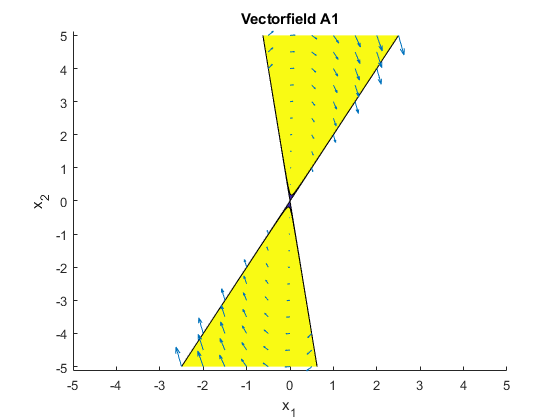


figure()
clf; hold on
%plotting the invariant map
[X,Y,Qp] = Qfield(Q,min,max,mapsize);
contourf(X,Y,Qp,[0 0.1])

%computing and plotting the vectorfield
[X,Y,u,v] = vectorfield(A2,min,max,vectorsize); %computing vectorsfield
[X,Y,Qp] = Qfield(Q,min,max,vectorsize); %recomputing feasible area to create binary map
map = zeros(length(u)); map(Qp>=0) = 1;
quiver(X,Y,u.*map,v.*map) %plotting the mapped vectorfield
title('Vectorfield A1')
xlabel('x_1'); ylabel('x_2')

hold off

figure()
x = min:stepsize:max

x =    -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000


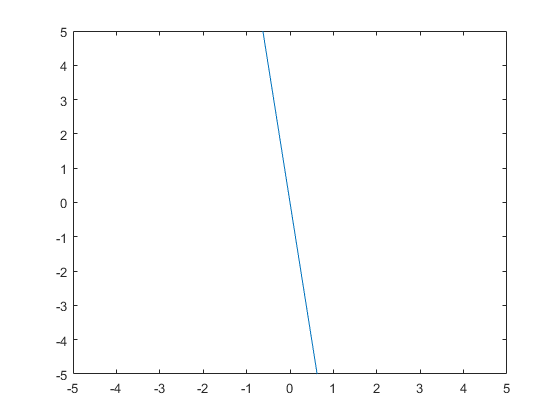

plot(x,-8*x)
ylim([-5,5]); xlim([-5,5])

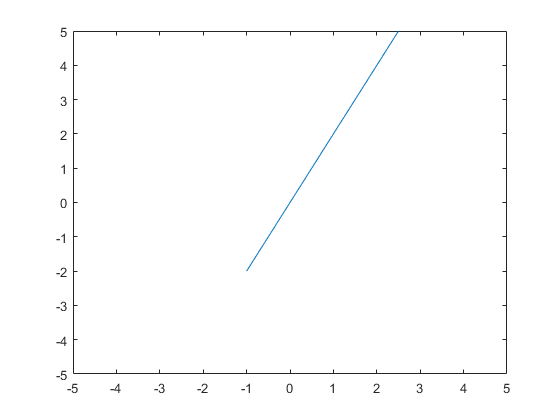


plot(x,2*x)
ylim([-5,5]); xlim([-5,5])

eig(A1)

ans =   -1.0000 +31.6228i
  -1.0000 -31.6228i


eig(A2)

ans =    1.0000 +31.6228i
   1.0000 -31.6228i


syms x y 
X = [x; y]

$$X = \left(\begin{array}{c} x\\ y \end{array}\right)$$

X.'*Q*X

$$ans = y\,\left(6\,x+2\,y\right)-x\,\left(32\,x-6\,y\right)$$

simplify(X.'*Q*X)

$$ans = -32\,x^{2}+12\,x\,y+2\,y^{2}$$